clear

addpath('matlab_functions\')

#### Compute $\Phi$

Model = myModel;

freqs = 100:100:10000; % (Hz)

freqs = reshape(freqs, 1,1,[]);
Phi = zeros(size(Model.sensors.positions,2), size(Model.voxels.center,2), length(freqs));

for k = 1:length(freqs)
    tic
    S_sigma = Model.Sensitivity(freqs(k));
    Phi(:,:,k) = -S_sigma .* Model.voxels.sigma;
    fprintf('Compute %g Hz sensitivity took %.2f seconds\n', freqs(k), toc)
end

Compute 100 Hz sensitivity took 32.30 seconds
Compute 200 Hz sensitivity took 3.93 seconds
Compute 300 Hz sensitivity took 3.98 seconds
Compute 400 Hz sensitivity took 4.00 seconds
Compute 500 Hz sensitivity took 3.98 seconds
Compute 600 Hz sensitivity took 4.00 seconds
Compute 700 Hz sensitivity took 4.03 seconds
Compute 800 Hz sensitivity took 4.17 seconds
Compute 900 Hz sensitivity took 3.92 seconds
Compute 1000 Hz sensitivity took 4.02 seconds
Compute 1100 Hz sensitivity took 3.93 seconds
Compute 1200 Hz sensitivity took 3.92 seconds
Compute 1300 Hz sensitivity took 3.94 seconds
Compute 1400 Hz sensitivity took 3.94 seconds
Compute 1500 Hz sensitivity took 3.90 seconds
Compute 1600 Hz sensitivity took 3.90 seconds
Compute 1700 Hz sensitivity took 3.88 seconds
Compute 1800 Hz sensitivity took 3.91 seconds
Compute 1900 Hz sensitivity took 3.87 seconds
Compute 2000 Hz sensitivity took 3.90 seconds
Compute 2100 Hz sensitivity took 3.88 seconds
Compute 2200 Hz sensitivity took 3.90 seco


voxels_center = Model.voxels.center;

fname = sprintf('data/Phi_%s.mat', datetime('now','Format','MMdd-HHmm'));
save(fname, 'freqs','Phi','voxels_center', "-v7.3");

clear

#### Visualize $\Phi$

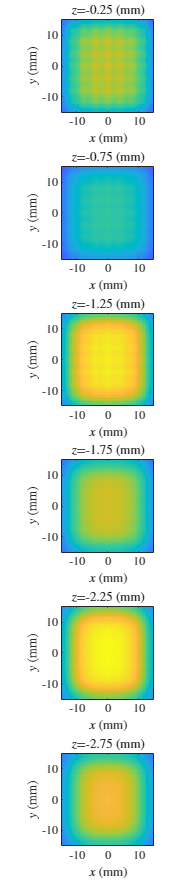

freq = 1000;

load('data\Phi.mat')
Phi = Phi(:,:,freqs == freq);
VisualizePhi(real(Phi), voxels_center)

function VisualizePhi(Phi, voxels_center, sensor_idxs)

seperate = false;

if nargin >= 3
    C = vecnorm(Phi(sensor_idxs,:), 2, 1);
else
    C = vecnorm(Phi               , 2, 1);
end

z = unique(voxels_center(3,:));
z = sort(z, 'descend');

if ~seperate
    figure
    tl = tiledlayout(length(z),1, 'TileSpacing','tight', 'Padding','none');
    set(gcf, 'Position',[10 10 flip(tl.GridSize) .* [300 250]])
end

for k = 1:length(z)
    mask = voxels_center(3,:) == z(k);
    Clayer = reshape(C(mask), sqrt(sum(mask)),[]).';

    x = [min(voxels_center(1,mask)) max(voxels_center(1,mask))] * 1e3;
    y = [min(voxels_center(2,mask)) max(voxels_center(2,mask))] * 1e3;

    if ~seperate
        nexttile
    else
        figure('Position',[10 10 900 800])
        tiledlayout(1,1, 'TileSpacing','none', 'Padding','none')
        nexttile
    end

    imagesc(x, y, Clayer, [0 max(C)])
    axis square xy
    title(sprintf('$z$=%g (mm)',z(k)*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
end

end